# Homework 3

## A3.1

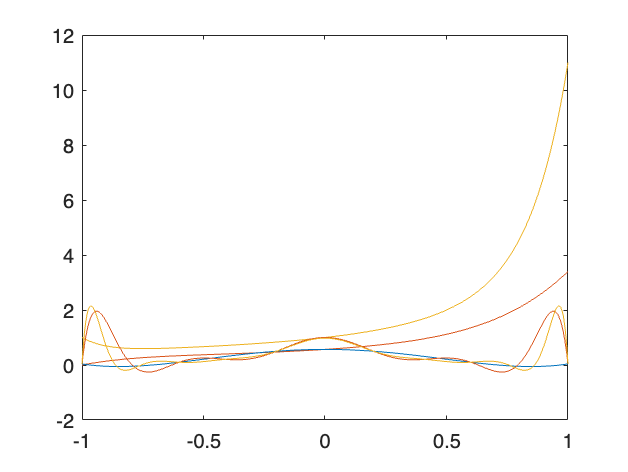

[x_6, y_6] = interpolation_3_1(6);
[x_11, y_11] = interpolation_3_1(11);
[x_16, y_16] = interpolation_3_1(16);

plot(x_6, y_6);
plot(x_11, y_11);
plot(x_16, y_16);

## T8.8

y = [3 5 10 -2 -3];

f = (c1 + c2*t + c3*t.^2) / (1 + d1*t + d2*t.^2);

function [plot_t, poly] = interpolation_3_1(n)
    t = linspace(-1, 1, n)';
    y = 1 ./ (1 + 25*t.^2);
    A = fliplr(vander(t));
    x = A \ y;

    plot_t = linspace(-1, 1, 400);
    poly = 0;
    for i = 1:n
        poly = poly + x(i)*plot_t.^(i - 1);
    end
end